[https://geoportal.statistics.gov.uk/datasets/ea5e1fb8a7c04f548f678f8998ddd41c_0/explore](https://geoportal.statistics.gov.uk/datasets/ea5e1fb8a7c04f548f678f8998ddd41c_0/explore) 

%% import and plot geojson data of UTLA boundaries and centroids-----------------------------------
filename = 'Counties_and_Unitary_Authorities_December_2017_EW_BSC_2022_-7354279468646832015.geojson';
geoTable = readgeotable(filename);% Read the GeoJSON file into a geospatial table
figure;
geoplot(geoTable.Shape, 'LineWidth', 1.5, 'DisplayName', 'UTLA Boundaries');
hold on;
geoplot(geoTable.LAT, geoTable.LONG, 'ro', 'MarkerSize', 2, 'DisplayName', 'Centroids');
hold on;

%% convert the northing/easting values into lat/lon and plot----------------------------------
bngCrs = projcrs(27700); % British National Grid (EPSG:27700)
[UTLAdata.lat, UTLAdata.lon] = projinv(bngCrs, UTLAdata.e, UTLAdata.n);
geoplot(UTLAdata.lat, UTLAdata.lon, 'bx', 'MarkerSize', 6, 'DisplayName', 'My Centroids');
legend;
hold on;

# still a few differences in boundaries but pretty good (see northampton) 

let's update the centroids of the utlas with these centroids and make the gravity models again and see if they are better predictions (look at the residuals). need to check if a new better centroid exists before I change it.

- I think the places that are underpredicted will mostly be fixed (the engulfing issue), but not the overpredictions

- would be interesting to see if there is more of a difference in the origin and destination constrained now

- actually it would make the underpredictions even greater because the centre moves further away. 

- need a model which can reflect transport links

change the centres

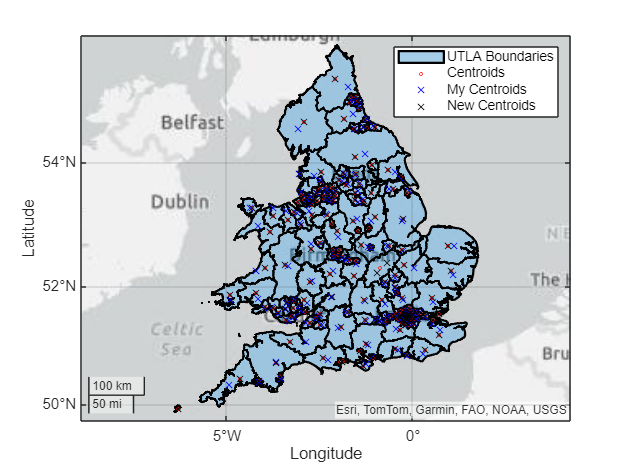

%% confirm which lat and long to use as the centroid--------------------------------------------------------------------------------------------
for i = 1:length(UTLAdata.label)
    for j = 1:length(UTLAdata.label)
        if UTLAdata.label(i) == geoTable.CTYUA17NM(j)
            UTLAdata.latchecked(i) = geoTable.LAT(j);
            UTLAdata.lonchecked(i) = geoTable.LONG(j);
        end
    end
end

for i = 1:length(UTLAdata.label)
    if UTLAdata.latchecked(i) == 0
        UTLAdata.latchecked(i) = UTLAdata.lat(i);
        UTLAdata.lonchecked(i) = UTLAdata.lon(i);
    end
end
% 55, 58, 59
geoplot(UTLAdata.latchecked, UTLAdata.lonchecked, 'kx', 'MarkerSize', 6, 'DisplayName', 'New Centroids');



%% fill distance matrix with new centroids (now lat/lon coords)---------------------------------------------------------------------------
% the index of this matrix is the origin and the destination resepctively
UTLAdata.distanceMatrixImproved = zeros(174,174);
% loop through all areas, calculate distance and insert into new matrix
for x = 1:1:length(UTLAdata.code)
    for y = 1:1:length(UTLAdata.code)
        UTLAdata.distanceMatrixImproved(x,y) = haversine([UTLAdata.latchecked(x) UTLAdata.latchecked(y)],[UTLAdata.lonchecked(x) UTLAdata.lonchecked(y)])/1000;
    end
end

%% return to q1c_1.mlx and run again with distanceMatrixImproved and observe change-------------------------------------------------------------

housekeeping

clear x y i j filename bngCrs;